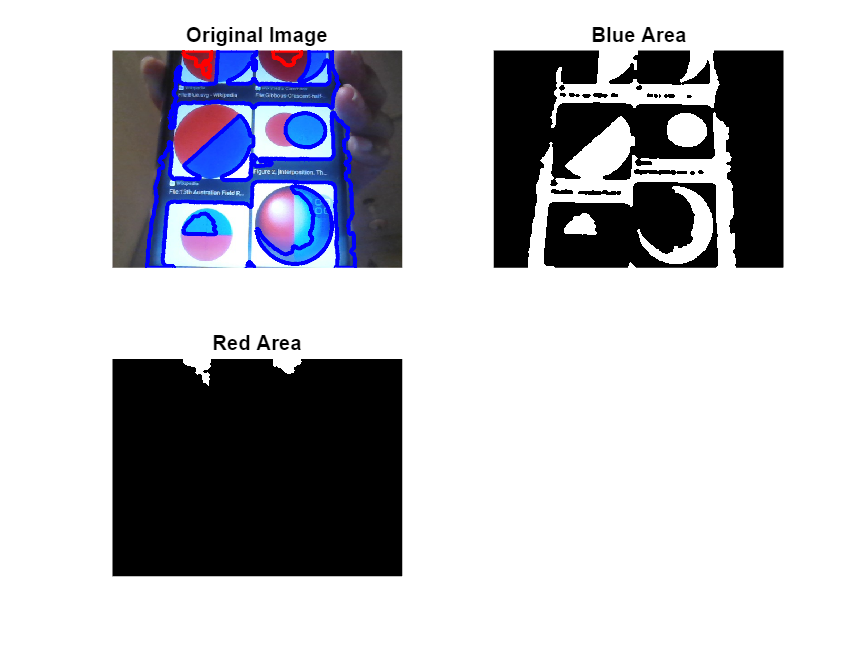

% Create webcam object
cam = webcam;

% Capture single image from webcam
image = snapshot(cam);

% Convert RGB image to HSV color space
I = rgb2hsv(image);

% Define thresholds for blue color
blueChannel1Min = 0.544;
blueChannel1Max = 0.677;
blueChannel2Min = 0.513;
blueChannel2Max = 1.000;
blueChannel3Min = 0.000;
blueChannel3Max = 1.000;

% Create blue mask based on chosen histogram thresholds
blueMask = (I(:,:,1) >= blueChannel1Min) & (I(:,:,1) <= blueChannel1Max) & ...
           (I(:,:,2) >= blueChannel2Min) & (I(:,:,2) <= blueChannel2Max) & ...
           (I(:,:,3) >= blueChannel3Min) & (I(:,:,3) <= blueChannel3Max);

% Define thresholds for red color
redChannel1Min = 0.954;
redChannel1Max = 0.009;
redChannel2Min = 0.709;
redChannel2Max = 1.000;
redChannel3Min = 0.000;
redChannel3Max = 1.000;

% Create red mask based on chosen histogram thresholds
redMask = ((I(:,:,1) >= redChannel1Min) | (I(:,:,1) <= redChannel1Max)) & ...
          (I(:,:,2) >= redChannel2Min) & (I(:,:,2) <= redChannel2Max) & ...
          (I(:,:,3) >= redChannel3Min) & (I(:,:,3) <= redChannel3Max);

% Apply morphological operations
se = strel('disk', 4);
afterOpeningBlue = imopen(blueMask, se);
afterClosingBlue = imclose(afterOpeningBlue, se);
afterOpeningRed = imopen(redMask, se);
afterClosingRed = imclose(afterOpeningRed, se);

% Remove small objects
minObjectSize = 100; % Adjust this value based on the size of the objects you want to keep
filteredBlueMask = bwareaopen(afterClosingBlue, minObjectSize);
filteredRedMask = bwareaopen(afterClosingRed, minObjectSize);

% Object Counting
[~, blueObjectsCount] = bwlabel(filteredBlueMask);
[~, redObjectsCount] = bwlabel(filteredRedMask);

% Display results
figure;

subplot(2, 2, 1);
imshow(image);
title('Original Image');

subplot(2, 2, 2);
imshow(filteredBlueMask);
title('Blue Area');

subplot(2, 2, 3);
imshow(filteredRedMask);
title('Red Area');

% Display bounding boxes around detected blue objects
[Bblue, ~] = bwboundaries(filteredBlueMask, 'noholes');
subplot(2, 2, 1);
hold on;
for k = 1:length(Bblue)
    boundary = Bblue{k};
    plot(boundary(:,2), boundary(:,1), 'b', 'LineWidth', 2);
end
hold off;

% Display bounding boxes around detected red objects
[Bred, ~] = bwboundaries(filteredRedMask, 'noholes');
subplot(2, 2, 1);
hold on;
for k = 1:length(Bred)
    boundary = Bred{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
end
hold off;


% Close webcam object when done
clear cam;
